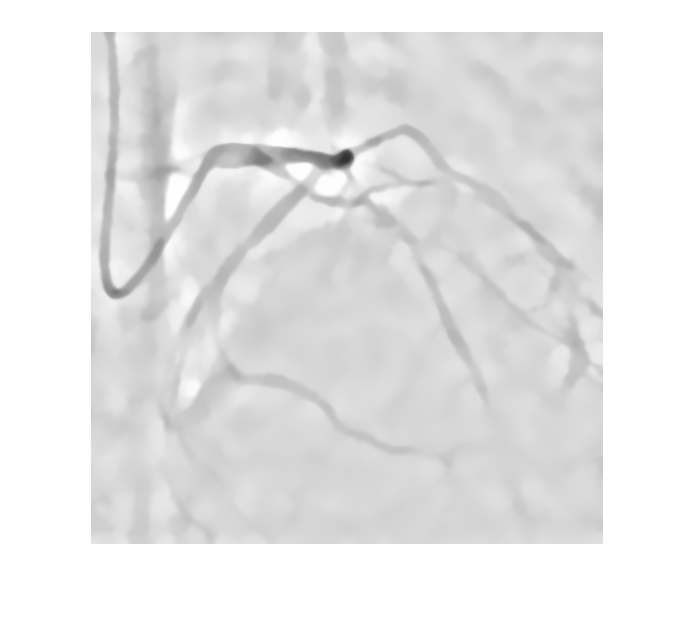

close all
A=imread('rankfiltered.jpg');
Ranked=im2gray(A);
noisyLAB = rgb2lab(A);
roi = [210,24,52,41];
patch = imcrop(noisyLAB,roi);
patchSq = patch.^2;
edist = sqrt(sum(patchSq,3));
patchSigma = sqrt(var(edist(:)));
DoS = 1.1*patchSigma;
denoisedLAB = imnlmfilt(noisyLAB,'DegreeOfSmoothing',DoS);
denoisedRGB = lab2rgb(denoisedLAB,'Out','uint8');
imshow(denoisedRGB)

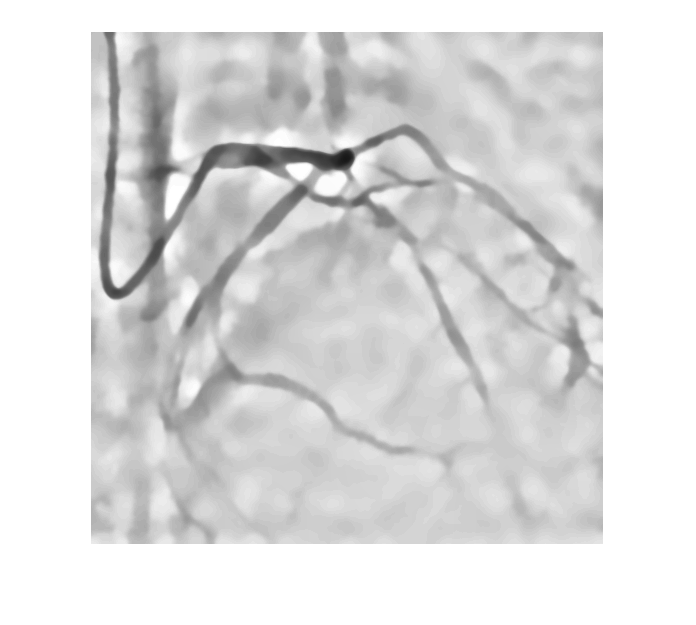



grimg=rgb2gray(denoisedRGB);
x=adapthisteq(grimg, 'numTiles', [8 8], 'nBins', 128);
imshow(x);

Test_Image=gray2d(denoisedRGB);
Resized_Image = imresize(Test_Image, [512 512]);
Converted_Image = im2double(Test_Image);
Lab_Image = rgb2lab(Resized_Image);
fill = cat(3, 1,0,0);
Filled_Image = bsxfun(@times, fill, Lab_Image);
Reshaped_Lab_Image = reshape(Filled_Image, [], 3);
[C, S] = pca(Reshaped_Lab_Image);
S = reshape(S, size(Lab_Image));
S = S(:, :, 1);

Gray_Image = (S-min(S(:)))./(max(S(:))-min(S(:)));

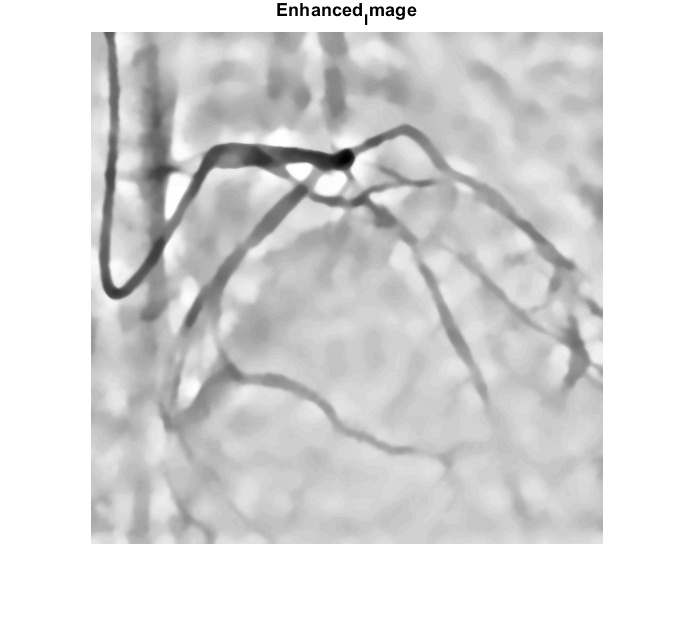

Enhanced_Image = adapthisteq(Gray_Image, 'numTiles', [8 8], 'nBins', 128);

figure, imshow(Enhanced_Image)
title('Enhanced_Image')

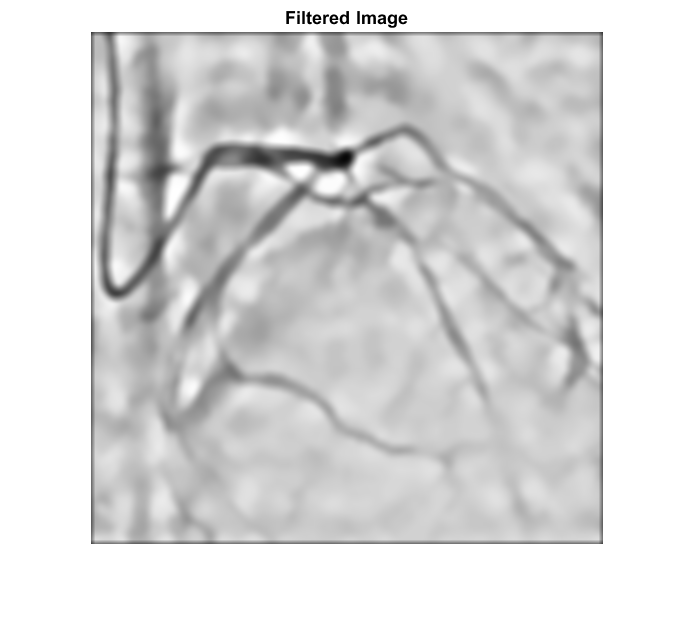

Avg_Filter = fspecial('average', [9 9]);
Filtered_Image = imfilter(Enhanced_Image, Avg_Filter);
figure, imshow(Filtered_Image)
title('Filtered Image')

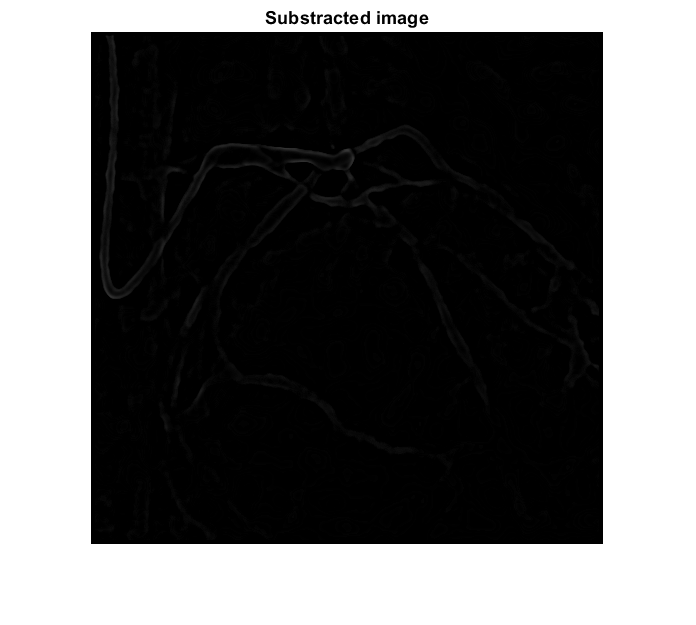

Substracted_Image = imsubtract(Filtered_Image,Enhanced_Image);
figure, imshow(Substracted_Image)
title('Substracted image')

% imwrite(S,"Substracted image.bmp")
% A=histeq(Substracted_Image);        %adjust contrast
% figure, imshow(A)
% title('Adjust contrast')

level = 0.02452%Threshold_Level(Substracted_Image);

level = 0.0245

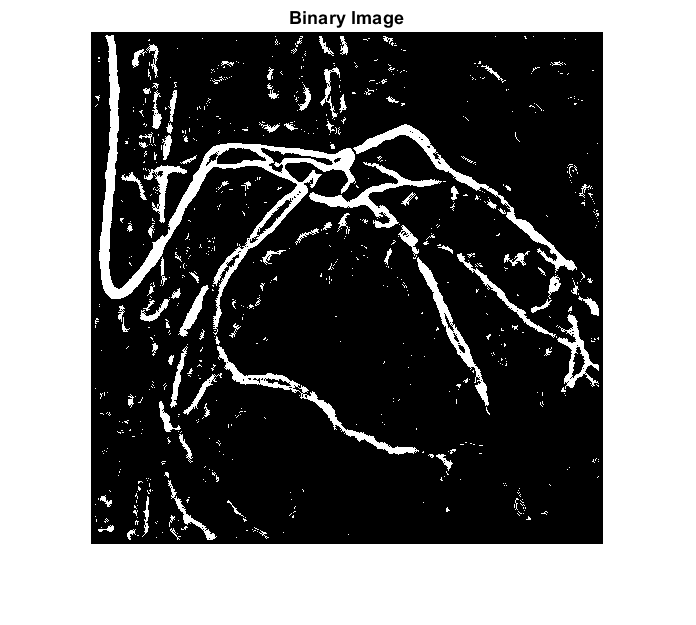

Binary_Image = imbinarize(Substracted_Image, level-0.008);
figure, imshow(Binary_Image)
title('Binary Image')

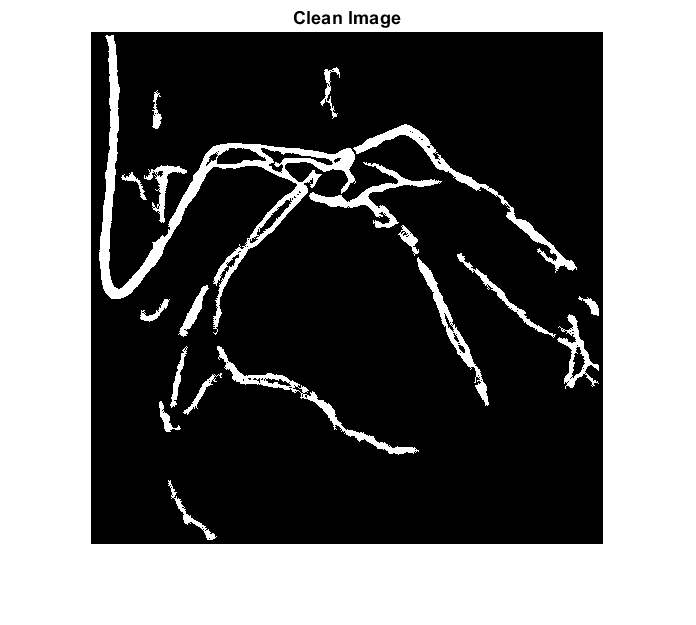

Clean_Image = bwareaopen(Binary_Image, 150);
figure, imshow(Clean_Image)
title('Clean Image')

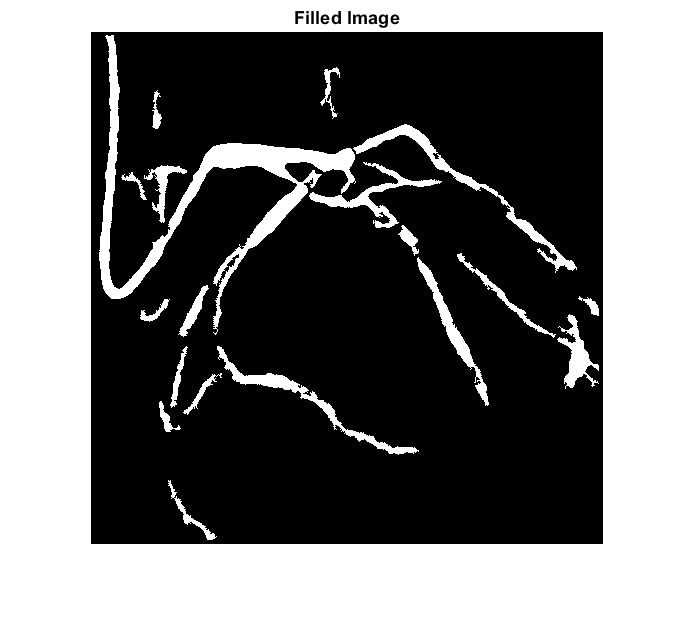

Filled_Image=imfill(Clean_Image,"holes");
figure, imshow(Filled_Image)
title('Filled Image')

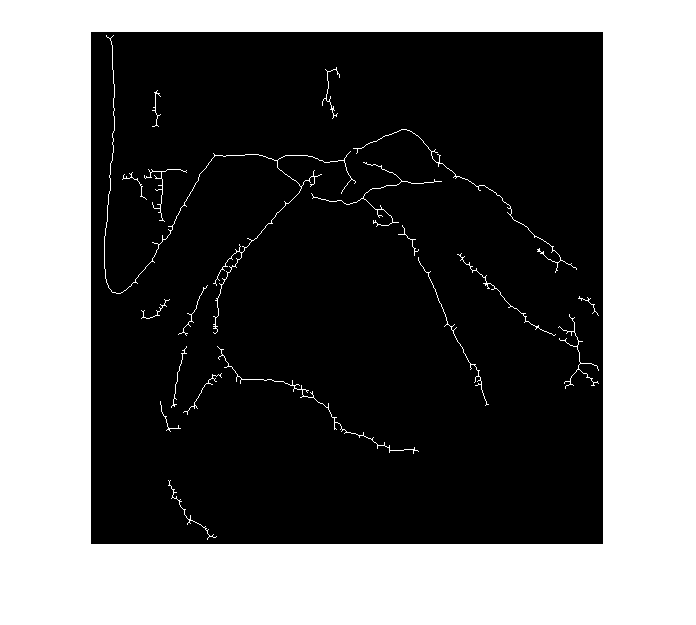

skeleton_img = bwmorph(Filled_Image,'skel',Inf);
imshow(skeleton_img)

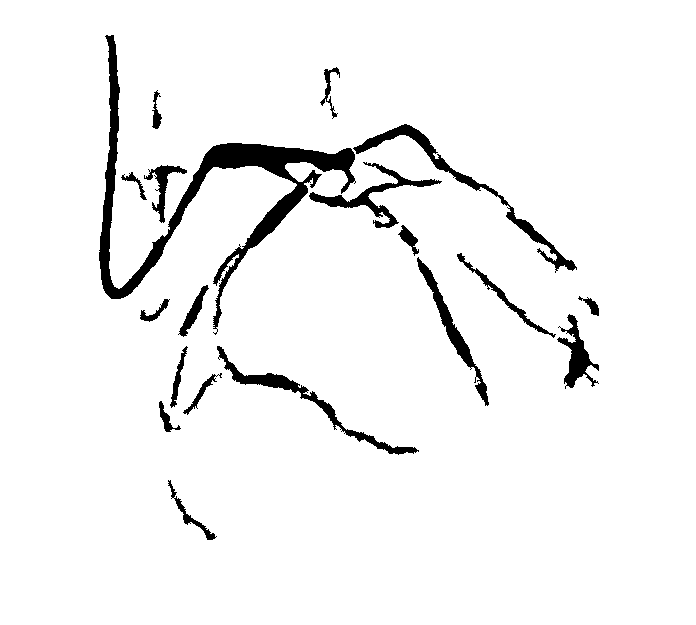

Complemented_Image = imcomplement(Filled_Image);
figure, imshow(Complemented_Image)

x = 1×3 uint8 row vector
    5   27   50


x = 1×3 uint8 row vector
    5   34   63


x = 1×3 uint8 row vector
    5   11   17


x = 1×3 uint8 row vector
    5   11   17


x = 1×3 uint8 row vector
    5   11   17


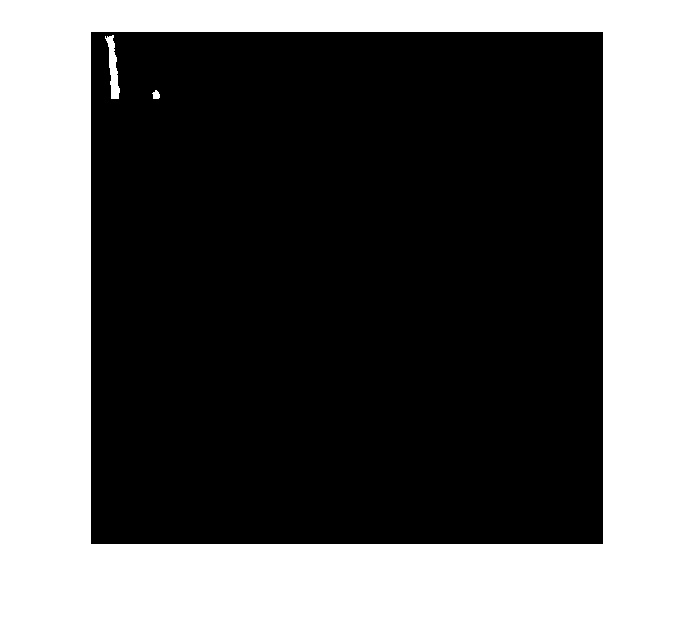

Unrecognized function or variable 'outx'.

Error in untitled>bpt2d (line 221)
out=[outx ;outy];

% ig=im2gray(Complemented_Image);
ig=skeleton_img;
[r,c,~]=size(ig);
x=8;
nr=r/x;
nc=c/x;
skip_x=nr/4; %32
skip_y=nc/4; %32

new=zeros(r,c);

count=0;
for i=0:skip_x:r-nr
    for j=0:skip_y:c-nc
        count=count+1;
        cropped_region =imcrop(ig,[j i nc nr]);
        cropped =imcrop(Ranked,[j i nc nr]);
%       cropped_region=adapthisteq(cropped_region, 'numTiles', [8 8], 'nBins', 128);
        str=string("croped/"+count+"image_orig.bmp");
        imwrite(cropped_region,str);
        
        x=[];
        [skel_pts,l]=bpt2d(cropped_region);
        new1=zeros(nc,nr);
        if l>4
            x=uint8(5:l/3:l);
            for i=1:length(x)
                Phi = segCroissRegion(5,cropped,skel_pts(x(i),2),skel_pts(x(i),1));
                new1=im2bw(new1);
                Phi=imresize(Phi,[64 64]);
                new1=imadd(new1,Phi);
            end
        end
        str=string("croped/"+count+"image.bmp");
        imwrite(new1 ,str);
        for k=1:nc
            for l=1:nr
                new(k+i,l+j)=new1(k,l) | new(k+i,l+j);
            end
        end
        imshow(new);

    end
end


% ne=bwareaopen(new,2000);
% figure,imshow(ne)
% gray=bi2gray(x);
% [BW,maskedImage] = segmentvessal(x,nfpts,nbpts)
% 
% imshowpair(BW,maskedImage,'montage')


SE=strel("disk",21);
dil=imdilate(Clean_Image,SE);


% dil=edge(dil,"canny");
% dil=imcomplement(dil);
figure, imshow(dil)
title('dilated image')

Complemented_Image=im21d(Complemented_Image);
dil=im21d(dil);

fpts=bpt(Complemented_Image)
bpts=bpt(dil)
[~, c]=size(fpts);
rf=randi(c,50,1)
[r, c]=size(bpts);
rb=randi(c,50,1)

nfpts=fpts(rf)
nbpts=bpts(rb)


Functions

%==============================graph cut===================================

function [BW,maskedImage] = segmentvessal(X,fpt,bpt)
X = imadjust(X);

% Graph cut
foregroundInd = fpt ;
backgroundInd = bpt ;
L = superpixels(X,1411,'IsInputLab',true);

% Convert L*a*b* range to [0 1]
scaledX = prepLab(X);
BW = lazysnapping(scaledX,L,foregroundInd,backgroundInd);

% Create masked image.
maskedImage = X;
maskedImage(~BW) = 0;
end
%================to convert gray 2d to 3 chanel(rgb) gray image=============
function [outImg]=gray2d(bw)
[r, c,l]=size(bw);
bw=imresize(bw,[r,c]);
if l==3
    outImg=bw;
else
  for x=1:3
    for i=1:r
       for j=1:c
           outImg(i,j,x)=bw(i,j);
       end
    end
 end
end

end

%==================to convert binary to unit8 image==========================
function [outImg]=bi2gray(bw)
[r, c]=size(bw);

outImg=ones([r c]);
for i=1:r
    for j=1:c
        if bw(i,j)==1
            outImg(i,j)=255;
        else
            outImg(i,j)=0;
        end
    end
end
end
%=======================to convert 2d image to 1d image=======================
function [outImg]=im21d(bw)
[r, c]=size(bw);

for i=1:r
    for j=1:c
        outImg((i-1)*c +j)=bw(i,j);
    end
end
end
%===========to extrect location of balck/white points  from 1d binary image==========
function [outImg]=bpt(bw)
[~, c]=size(bw);
x=1;
for i=1:c
    if bw(i)==0
        outImg(x)=i;
        x=x+1;
%     else
    end
end

end
%===========to extrect location of balck/white points  from 2d binary image==========
function [out,l]=bpt2d(bw)
[r, c]=size(bw);
x=1;
outx=[];
outy=[];
for j=1:r
    for i=1:c
        if bw(j,i)==1
            outx(x)=i;
            outy(x)=j;
            x=x+1;
%     else
        end
    end
end
out=[outx ;outy];
out=transpose(out);
l=length(out);
end
%=================region growing=======================
function Phi = segCroissRegion(tolerance,Igray,x,y)
if(x == 0 || y == 0)
    imshow(Igray,[0 255]);
    [x,y] = ginput(1);
end
Phi = false(size(Igray,1),size(Igray,2));
ref = true(size(Igray,1),size(Igray,2));
PhiOld = Phi;
Phi(uint8(x),uint8(y)) = 1;
while(sum(Phi(:)) ~= sum(PhiOld(:)))
    PhiOld = Phi;
    segm_val = Igray(Phi);
    meanSeg = mean(segm_val);
    posVoisinsPhi = imdilate(Phi,strel('disk',1,0)) - Phi;
    voisins = find(posVoisinsPhi);
    valeursVoisins = Igray(voisins);
    Phi(voisins(valeursVoisins > meanSeg - tolerance & valeursVoisins < meanSeg + tolerance)) = 1;
end

% Uncomment this if you only want to get the region boundaries
% SE = strel('disk',1,0);
% ImErd = imerode(Phi,SE);
% Phi = Phi - ImErd;
end
